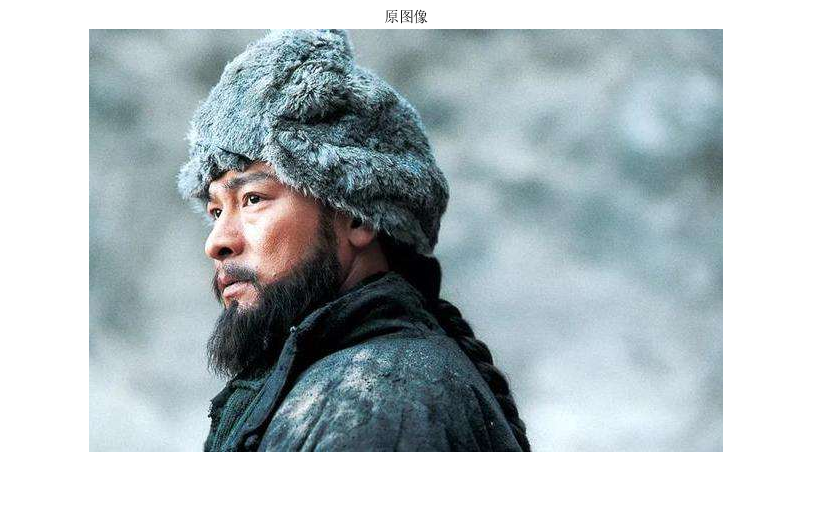

clc;
clear;
I=imread("09-刘德华.jpg");
I=im2double(I);
figure
imshow(I);
title("原图像");

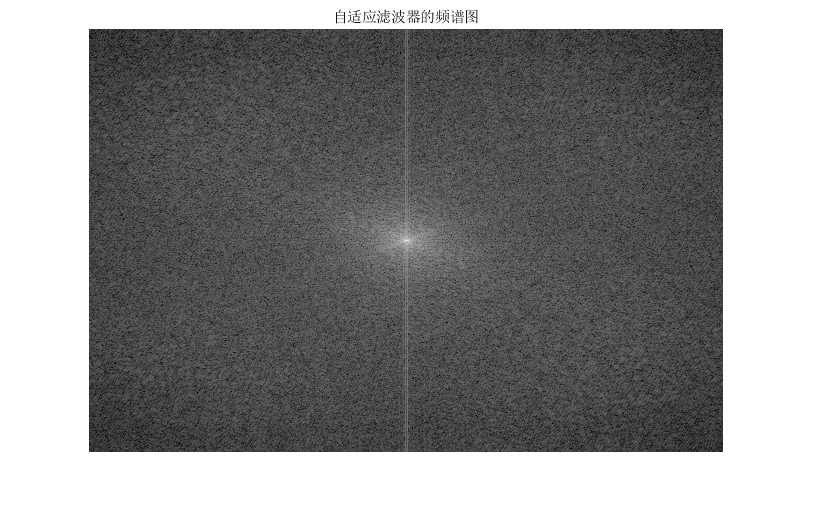

%求二维傅里叶变换
%设置三个通道的权值
a1=0.6;
a2=0.3;
a3=1-a1-a2;
%对图像进行傅里叶变换
Y=fftshift(fft2(I));
%加权得到自适应滤波器
H=a1*Y(:,:,1)+a2*Y(:,:,2)+a3*Y(:,:,3);
%进行对数变换
H=abs(log(1+H));
%归一化
H=H/max(H,[],'all');
%绘制滤波器频谱图
figure
imshow(H,[])
title('自适应滤波器的频谱图');

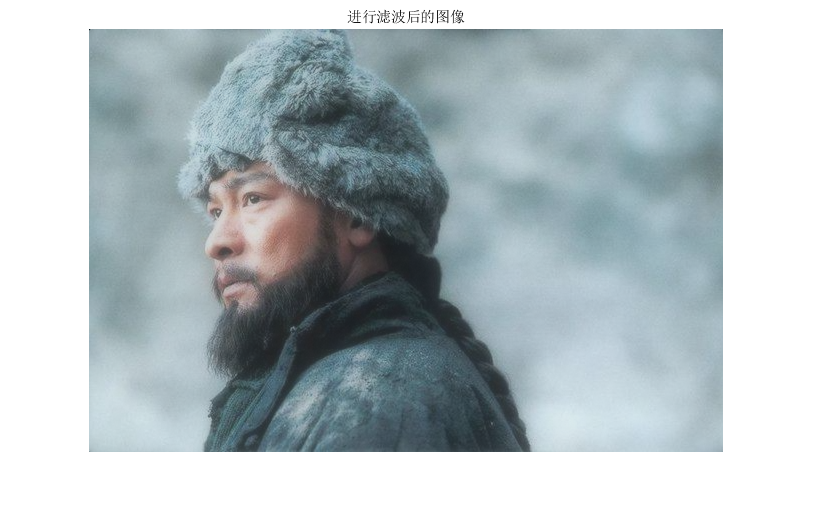

%对三个通道进行滤波
for i=1:3
    Y(:,:,i)=Y(:,:,i).*H;
end
%进行傅里叶反变换
I_filt=abs(ifft2(ifftshift(Y)));
%绘制结果
figure
imshow(I_filt,[]);
title('进行滤波后的图像');

%储存
imwrite(H,'自适应滤波器的频谱图.jpg','jpg');
imwrite(I_filt,'进行滤波后的图像.jpg','jpg');